## Analisi del sistema a ciclo aperto

### Modello in esame

Siano $m = 1kg$ la massa della mensola ed $l = 1m$ la lunghezza della staffa,$g = 9.81 \frac{m}{s^2}$l’accelerazione di gravità e $b = 0.1$ il coefficiente di attrito. L’impianto da controllare assegnato al gruppo di progetto è catturato dal seguente modello matematico: 


$$\begin{cases}
\dot x_1 =x_2 \\
\dot{x_2} = -\frac{g}{l} sin x_1- \frac{b}{ml^2}x_2+ \frac{u(t)}{ml^2}\\
y=x_1
\end{cases}$$


La funzione “ode45”, ordinary differential equation (ODE)  serve a simulare sistemi dinamici, poichè  un modello in tal caso viene considerato come un'equazione differenziale. 

La funzione "ode45" restituisce un vettore dei tempi e una matrice $x$ che contiene lo stato, quindi contiene i valori delle variabili di stato per ogni valore del tempo $t$. La matrice $x$ ha sulle righe le variabili di stato e sulle colonne i tempi.

Sintassi:

     
$$   [t,x]= ode45(fcn, tspan,x_0)$$


- $fcn$:  parametro che rappresenta la funzione da simulare, contenente la dinamica passata per riferimento

- $tspan$: è un parametro minimo che è la durata della simulazione, cioè quanto vogliamo simulare: è un vettore dei tempi matlab $[T_0, T_f]$ dal tempo iniziale al tempo finale.

- L'ultimo parametro $x_0$, indica le condizioni iniziali.

Di seguito verrà mostrato il comportamento del pendolo a ciclo aperto, ovvero senza l'uso del controllore.

Simulazione con x1_0 = 0, x2_0 = 0
Simulazione con x1_0 = 0.5, x2_0 = 0
Simulazione con x1_0 = 1, x2_0 = 0
Simulazione con x1_0 = 1.5, x2_0 = 0
Simulazione con x1_0 = 2, x2_0 = 0
Simulazione con x1_0 = 2.5, x2_0 = 0
Simulazione con x1_0 = 3, x2_0 = 0
Simulazione con x1_0 = 3.5, x2_0 = 0
Simulazione con x1_0 = 4, x2_0 = 0
Simulazione con x1_0 = 4.5, x2_0 = 0
Simulazione con x1_0 = 5, x2_0 = 0


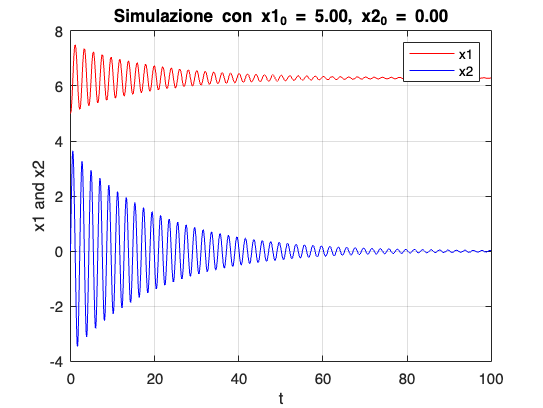

%mkdir('Immagini_Ciclo_Aperto');
%usare la linea di sopra eventualmente per salvare le immagini
tspan = [0 100];  % Intervallo di simulazione
x2_0 = 0;         % Condizione iniziale per x2
u = 0;            

% Valori iniziali e passo per il ciclo
x1_start = 0;
x1_end = 5;
x1_step = 0.5;

% Inizializzazione di x1
x1_0 = x1_start;

% Indice per numerare le figure
figIndex = 1;

% Ciclo while per iterare su x1
while x1_0 <= x1_end
    
    % Stampa il valore corrente di x1_0 per debug
    disp(['Simulazione con x1_0 = ', num2str(x1_0), ', x2_0 = ', num2str(x2_0)]);
    
    % Vettore delle condizioni iniziali correnti
    x0 = [x1_0 x2_0];

    % Esecuzione della simulazione con ode45
    [t, x] = ode45(@PWsimulink, tspan, x0, [], u);

    % Estrazione delle variabili di stato
    x1 = x(:, 1);
    x2 = x(:, 2);

    % Creazione di una nuova figura per ogni iterazione
    plot(t, x1, 'r');
    hold on;  % Mantiene lo stesso grafico per i plot successivi
    plot(t, x2, 'b');
    hold off;  % Rilascia il grafico per nuovi plot

    % Impostazioni grafiche per la figura corrente
    grid on;
    xlabel('t');
    ylabel('x1 and x2');
    legend('x1', 'x2');
    titleString = sprintf('Simulazione con x1_0 = %.2f, x2_0 = %.2f', x1_0, x2_0);
    title(titleString);

    % Incremento di x1 e indice figura per il prossimo ciclo
    x1_0 = x1_0 + x1_step;
    figIndex = figIndex + 1;
    
    pause(1); % Pausa di 1 secondo
    %saveas(gcf, sprintf('Immagini_Ciclo_Aperto/simulazione_%d.png', figIndex));
     %usare la linea di sopra eventualmente per salvare le immagini
end

Simulazione con x1_0 = 0, x2_0 = 0
Simulazione con x1_0 = 0.5, x2_0 = 0
Simulazione con x1_0 = 1, x2_0 = 0
Simulazione con x1_0 = 1.5, x2_0 = 0
Simulazione con x1_0 = 2, x2_0 = 0
Simulazione con x1_0 = 2.5, x2_0 = 0
Simulazione con x1_0 = 3, x2_0 = 0
Simulazione con x1_0 = 3.5, x2_0 = 0
Simulazione con x1_0 = 4, x2_0 = 0
Simulazione con x1_0 = 4.5, x2_0 = 0
Simulazione con x1_0 = 5, x2_0 = 0


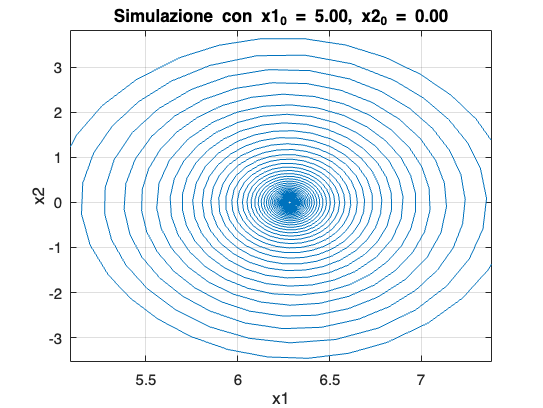


%% Piano delle fasi
% Inizializzazione di x1
x1_0 = x1_start;

% Indice per numerare le figure
figIndex = 1;

% Ciclo while per iterare su x1
while x1_0 <= x1_end
    
    % Stampa il valore corrente di x1_0 per debug
    disp(['Simulazione con x1_0 = ', num2str(x1_0), ', x2_0 = ', num2str(x2_0)]);
    
    % Vettore delle condizioni iniziali correnti
    x0 = [x1_0 x2_0];

    % Esecuzione della simulazione con ode45
    [t, x] = ode45(@PWsimulink, tspan, x0, [], u);

    % Estrazione delle variabili di stato
    x1 = x(:, 1);
    x2 = x(:, 2);

    % Creazione di una nuova figura per ogni iterazione
     % Subplot per il piano delle fasi
    plot(x1, x2);
    
    xlim([5.09 7.38])
    ylim([-3.53 3.81])

    % Impostazioni grafiche per la figura corrente
    grid on;
    xlabel('x1');
    ylabel('x2');
    titleString = sprintf('Simulazione con x1_0 = %.2f, x2_0 = %.2f', x1_0, x2_0);
    title(titleString);



    % Incremento di x1 e indice figura per il prossimo ciclo
    x1_0 = x1_0 + x1_step;
    figIndex = figIndex + 1;
    
    % Opzionale: pausa tra le figure per osservare i plot uno per uno
    pause(1); % Pausa di 1 secondo
    %saveas(gcf, sprintf('Immagini_Ciclo_Aperto/piano_fasi_%d.png', figIndex));
    %usare la linea di sopra eventualmente per salvare le immagini
end

function x_dot=PWsimulink(t,x,u)
    l=1;       % lunghezza del pendolo in metri
    g=9.81;    % accelerazione di gravità in m/s^2
    b=0.1;     % coefficiente di smorzamento
    m=1;       % massa del pendolo in kg

    x1=x(1);
    x2=x(2);

    x1_dot=x2;
    x2_dot=(-g/l)*sin(x1)-(b/(m*l^2))*x2; % la u in questo caso è nulla in quanto stamo analizzando il modello a ciclo aperto,
    % quindi in assenza di un controllore
    
    x_dot=[x1_dot x2_dot]';
end